clear
clc
S11 = importdata("S11.dat")

S11 = 包含以下字段的 struct :
          data: [101×2 double]
      textdata: {2×2 cell}
    colheaders: {'"Frequency"[Hz]'  '"SParameter_port_1_port_1 [dB]"'}


Freq = S11.data(:,1);
S11 = S11.data(:,2);

MWC = importdata("MWC.dat")

MWC = 包含以下字段的 struct :
          data: [101×11 double]
      textdata: {2×11 cell}
    colheaders: {1×11 cell}


MS = importdata("MS.dat")

MS = 包含以下字段的 struct :
          data: [101×7 double]
      textdata: {2×7 cell}
    colheaders: {'"Frequency"[Hz]'  '"Mode index = 1  []"'  '"Mode index = 2  []"'  '"Mode index = 3  []"'  '"Mode index = 4  []"'  '"Mode index = 5  []"'  '"Mode index = 6  []"'}


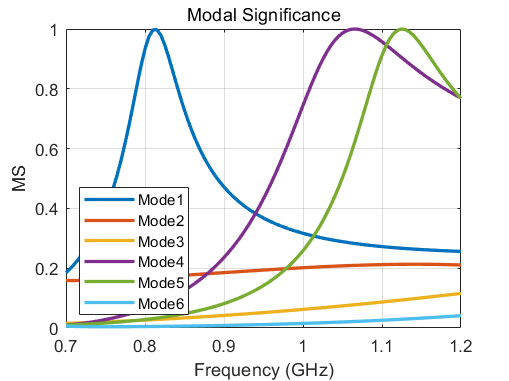


figure(1)
plot(Freq/1e9, MS.data(:,2), LineWidth=2)
hold on
for i = 3:width(MS.data)
    %     if max(MS.data(:,i)) >= 0.5
    plot(Freq/1e9, MS.data(:,i), LineWidth=2)
    %     end
end
hold off
grid on
title(['Modal Significance'])
xlabel('Frequency (GHz)')
ylabel('MS')
legend('Mode1','Mode2','Mode3','Mode4','Mode5','Mode6', Location='southwest')

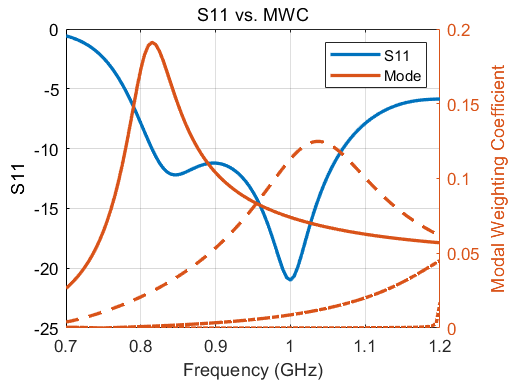




figure(2)
plot(Freq/1e9, S11, LineWidth=2)
hold on
yyaxis right
for i = 2:width(MWC.data)
    if max(MWC.data(:,i)) >= 0.01
        plot(Freq/1e9, MWC.data(:,i), LineWidth=2)
    end
end
grid on
legend('S11', 'Mode')
yyaxis left
title('S11 vs. MWC')
xlabel('Frequency (GHz)')
ylabel('S11')
yyaxis right
ylabel('Modal Weighting Coefficient')
hold off